Alen Mehmedbegovic         301476201 

Question 1

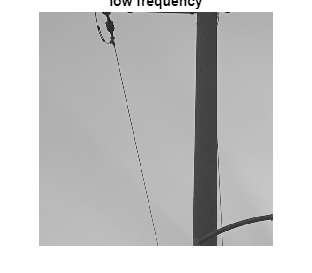

HP = imread('toysflash.png');
HP = HP(1:500, 200:699, :);   % Crop
HP = im2double(HP);         
HP = rgb2gray(HP);        % Convert to greyscale 
imwrite(HP, "HP.png");

LP = imread("BeautifulCroatia.jpeg");
LP = LP(1:500, 200:699, :);   % Crop
LP = im2double(LP);         
LP = rgb2gray(LP);        % Convert to greyscale 
imwrite(LP, "LP.png");

imshow(LP);
title('low frequency');

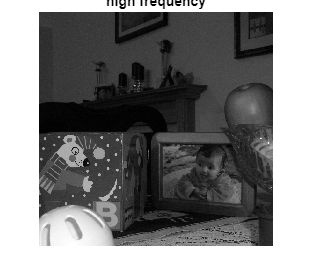

imshow(HP);
title('high frequency')

Question 2

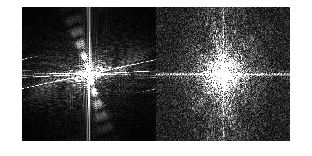

LP_FT = fft2(LP);
HP_FT = fft2(HP);
imshow([fftshift(abs(LP_FT)) fftshift(abs(HP_FT))]/ 50)

imwrite(fftshift(abs(LP_FT))/50, "LP-freq.png");
imwrite(fftshift(abs(HP_FT))/50, "HP-freq.png");
% As we can see, low frequency image is more concentrated in center and
% high frequency is more spread out across image. As expected 

Question 3

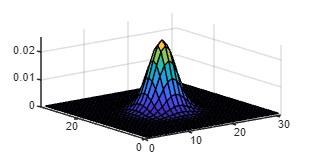

% Sobel kernel
sob = [-1 0 1; -2 0 2; -1 0 1];

% Gaussian kernel
gauss = fspecial('gaussian', 31, 2.5);
% gaussian fliter, with 31x31 dimensions and SD 2.5
% we choose odd numbers for the dimensions as the size of pixels 
% are discrete so if we want to center one kernel on top of a pixel 
% it needs to be odd
saveas(surf(gauss), "gaus-surf.png"); 

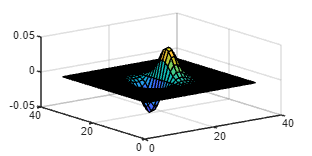


% DoG kernel
DoG = conv2(gauss, sob);
saveas(surf(DoG), "dog-surf.png"); 


% Apply gaussian filter to LP and HP 
LPgaus = imfilter(LP,gauss);
HPgaus = imfilter(HP,gauss);
% Compute frequency representations of them
LPgaus_FT = fft2(LPgaus);
HPgaus_FT = fft2(HPgaus); 
imwrite(LPgaus, "LP-flit.png");
imwrite(HPgaus, "HP-flit.png");
imwrite(abs(fftshift(LPgaus_FT)), "LP-flit-freq.png");
imwrite(abs(fftshift(HPgaus_FT)), "HP-flit-freq.png");

% Compute fourier transform of DoG kernel 
DoGFT = fft2(DoG, 500, 500);
% Multiplication in spatial = convolution in frequency 
% F(g*h) = F(g)F(h)  <==> F^-1(g*h) = F^-1(g)F^-1(h)
LPfiltfreq = DoGFT.*LPgaus_FT;
imwrite(abs(fftshift((LPfiltfreq))), "LP-dogfilt-freq.png")

HPfiltfreq = DoGFT.*HPgaus_FT;
imwrite(fftshift(abs(HPfiltfreq)), "HP-dogfilt-freq.png")

LPfiltspace = ifft2(LPfiltfreq);
imwrite(LPfiltspace, "LP-dogfilt.png")

HPfiltspace = ifft2(HPfiltfreq);
imwrite(HPfiltspace, "HP-dogfilt.png")

Question 4

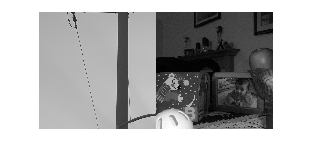

LP_subsamp2 = LP(1:2:end, 1:2:end);
HP_subsamp2 = HP(1:2:end, 1:2:end);
imshow([LP_subsamp2 HP_subsamp2]);

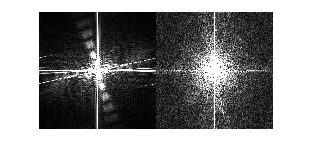


LP_FT_subsamp2 = LP_FT(1:2:end, 1:2:end);
HP_FT_subsamp2 = HP_FT(1:2:end, 1:2:end);
imshow([fftshift(abs(LP_FT_subsamp2)) fftshift(abs(HP_FT_subsamp2))]/ 50)

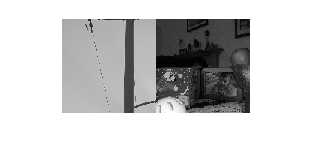


imwrite(LP_subsamp2, "LP-sub2.png")
imwrite(HP_subsamp2, "HP-sub2.png")
imwrite(fftshift(abs(LP_FT_subsamp2))/50, "LP-sub2-freq.png");
imwrite(fftshift(abs(HP_FT_subsamp2))/50, "HP-sub2-freq.png");



LP_subsamp4 = LP(1:4:end, 1:4:end);
HP_subsamp4 = HP(1:4:end, 1:4:end);
imshow([LP_subsamp4 HP_subsamp4]);

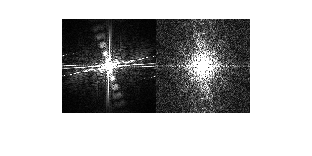


LP_FT_subsamp4 = LP_FT(1:4:end, 1:4:end);
HP_FT_subsamp4 = HP_FT(1:4:end, 1:4:end);
imshow([fftshift(abs(LP_FT_subsamp4)) fftshift(abs(HP_FT_subsamp4))]/ 50)


imwrite(LP_subsamp2, "LP-sub4.png")
imwrite(HP_subsamp2, "HP-sub4.png")
imwrite(fftshift(abs(LP_FT_subsamp4))/50, "LP-sub4-freq.png");
imwrite(fftshift(abs(HP_FT_subsamp4))/50, "HP-sub4-freq.png");



HP_FILT2_gauss = fspecial('gaussian', 31, 1);
HP_FILT2 = imfilter(HP, HP_FILT2_gauss);
HP_FILT2_subsamp = HP_FILT2(1:2:end, 1:2:end);

HP_FILT4_gauss = fspecial('gaussian', 51, 1.5);
HP_FILT4 = imfilter(HP, HP_FILT4_gauss);
HP_FILT4_subsamp = HP_FILT4(1:4:end, 1:4:end);

imwrite(HP_FILT2_subsamp, "HP-sub2-aa.png");
imwrite(HP_FILT4_subsamp, "HP-sub4-aa.png");
imwrite(abs(fftshift(fft2(HP_FILT2_subsamp)))/50, "HP-sub2-aa-freq.png");
imwrite(abs(fftshift(fft2(HP_FILT4_subsamp)))/50, "HP-sub4-aa-freq.png");

Question 5

%default parameters given by matlab 
[cannyedgeLP, threshLP] = edge(LP, 'canny');
[cannyedgeHP, threshHP] = edge(HP, 'canny');
threshLP

threshLP =     0.0063    0.0156


% The default values given by matlab give false edges on the wooden pole,
% so we can decrease the high threshold and increase the low threshold 
% to make sure less edges are present  
[cannyedgeLPopt, threshLPopt] = edge(LP, 'canny', [0.007, 0.02]);
imwrite(cannyedgeLPopt, "LP-canny-optimal.png");

threshHP

threshHP =     0.0312    0.0781


% We can see some of the edges of the present box and objects in background
% are skipped in the HP image with the MATLAB given thresholds, so we can lower 
% the high threshold to make sure more edges get captured
[cannyedgeHPopt, threshHPopt] = edge(HP, 'canny', [0.0312, 0.06]);
imwrite(cannyedgeHPopt, "HP-canny-optimal.png");

% lower low 
[cannyedgeLPlowlow, threshLPlowlow] = edge(LP, 'canny', [0.005 0.02]);
[cannyedgeHPlowlow, threshHPlowlow] = edge(HP, 'canny', [0.025 0.06]);
imwrite(cannyedgeLPlowlow, "LP-canny-lowlow.png");
imwrite(cannyedgeHPlowlow, "HP-canny-lowlow.png");

% higher low 
[cannyedgeLPhighlow, threshLPhighlow] = edge(LP, 'canny', [0.01 0.02]);
[cannyedgeHPhighlow, threshHPhighlow] = edge(HP, 'canny', [0.035 0.06]);
imwrite(cannyedgeLPhighlow, "LP-canny-highlow.png");
imwrite(cannyedgeHPhighlow, "HP-canny-highlow.png");

% lower high 
[cannyedgeLPlowhigh, threshLPlowhigh] = edge(LP, 'canny', [0.007 0.01]);
[cannyedgeHPlowhigh, threshHPlowhigh] = edge(HP, 'canny', [0.0312 0.05]);
imwrite(cannyedgeLPlowhigh, "LP-canny-lowhigh.png");
imwrite(cannyedgeHPlowhigh, "HP-canny-lowhigh.png");

% higher high 
[cannyedgeLPhighhigh, threshLPhighhigh] = edge(LP, 'canny', [0.007 0.03]);
[cannyedgeHPhighhigh, threshHPhighhigh] = edge(HP, 'canny', [0.0312 0.08]);
imwrite(cannyedgeLPhighhigh, "LP-canny-highhigh.png");
imwrite(cannyedgeHPhighhigh, "HP-canny-highhigh.png");